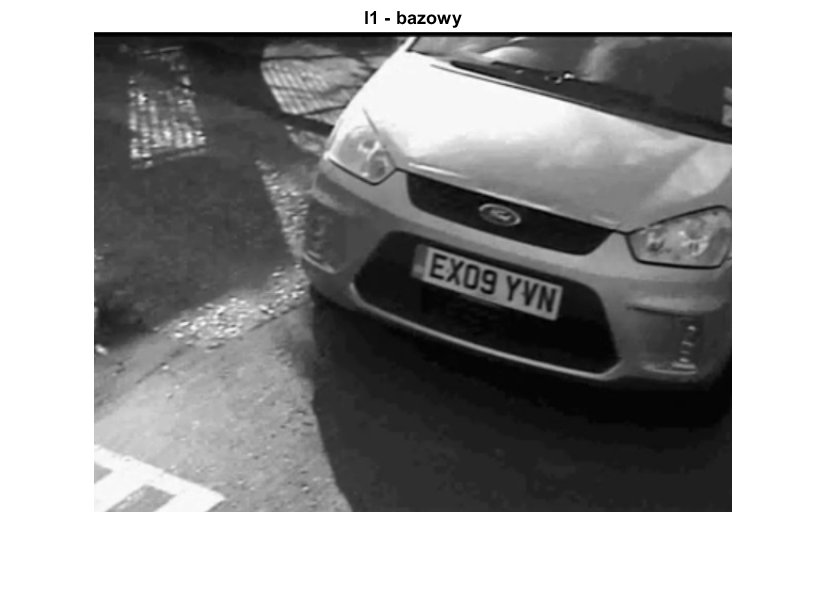

clc; clear all;close all;
close all; clear all; clc
I = imread('car1.jpg');
% ---- ewentualne przejście do skali szarości
I1 =  double(rgb2gray(I));
figure; imshow(I1,[]); title('I1 - bazowy')

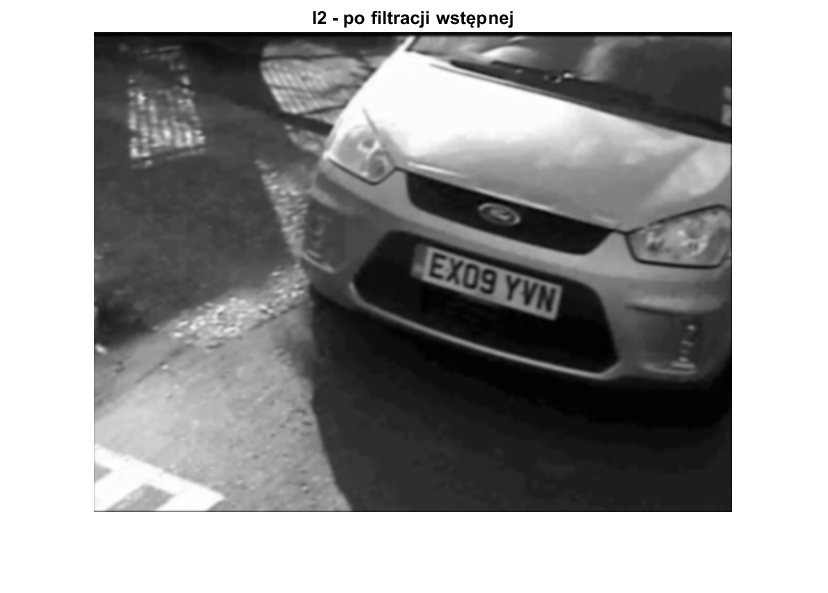


%----- filtracja wstępna:generowanie maski filtru Gaussa lub innego filtru
h = fspecial('gaussian', 32,1 ); % generowanie maski filtru Gaussa...
% h = [];  % generowanie maski innego filtru...
I2 = imfilter(I1, h); figure;imshow(I2,[]);title('I2 - po filtracji wstępnej')

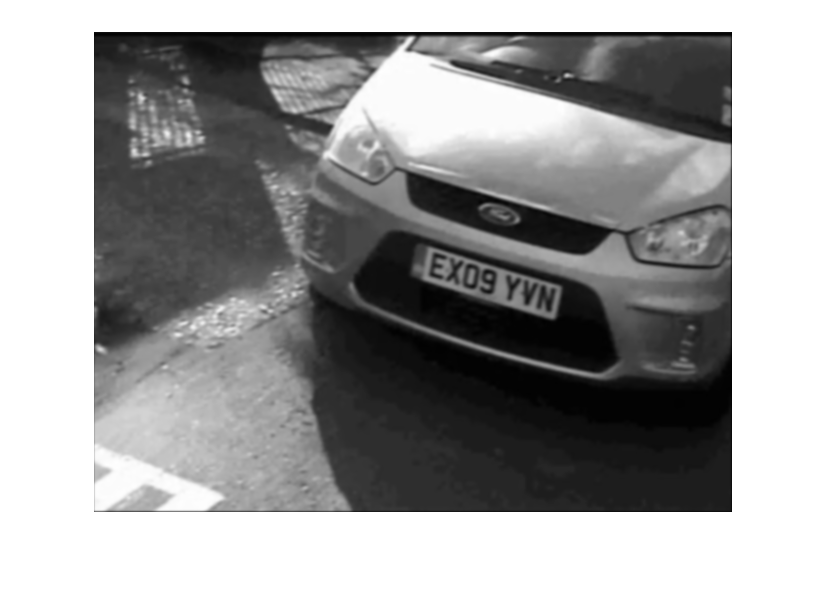

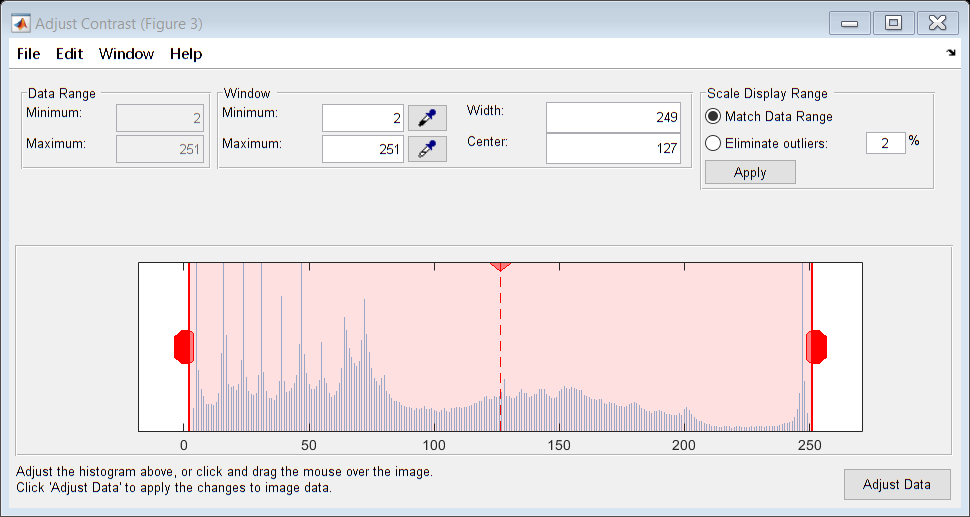

I2 = quant(I2,1); % kwantyzacja po filtracji [0 255]

image = figure;
imshow(I2,[]);
% -----  dobór progu ------
imcontrast(image);


%lt =   ;      % dolny prog binaryzacji
%ut =   ;     % gorny prog binaryzacji

% ----- binaryzacja -------
B1 = I2; 
B1(B1<lt)=0; % usunięcie pikseli o wartościach mniejszych od lt 

Error using <a href="matlab:matlab.internal.language.introspective.errorDocCallback('lt')" style="font-weight:bold"> < </a>
Not enough input arguments.

B1(B1>ut)=0; % usunięcie pikseli o wartościach większych od ut 
B1(B1>0) = 1; % przypisanie pozostałym o wartościom 1
figure;imshow(B1,[]);title('B1 - po binaryzacji')

% -- operacje morfologiczne (kolejność i liczba iteracji do wyboru):
B1 = bwmorph(B1,'dilate',1);figure;imshow(B1,[]);title('B1 - po operacji morfologicznej dylatacji')
B1 = bwmorph(B1,'erode',1);figure;imshow(B1,[]);title('B1 - po operacji morfologicznej erozji')
B1 = imfill(B1,4,'holes');figure;imshow(B1,[]);title('B1 - po operacji morfologicznej wypełanienia')
%B1 = bwareaopen(B1,  ); figure;imshow(B1,[]);title('B1 - po operacji morfologicznej usunięcia elementów o powierzchni mniejszej niż X pikseli')

% -- detekcja krawędzi (kolejność i liczba iteracji do wyboru):

Isob = edge(B1,'sobel'); figure; imshow(Isob,[]); title('Detekcja krawędzi filtrem Sobela')
%Ican = edge(B1,'canny', ); figure; imshow(Ican,[]); title('Detekcja krawędzi filtrem Cannego')